height = 100;
width = 100;
hold on
qstart = [30 20];
qgoal = [90 50];
axis ([0 width 0 height]);
b=eudist(qstart,qgoal);

slop = abs(qgoal(2)-qstart(2))/(qgoal(1)-qstart(1))

slop =                        0.5


qcenter = [qstart(1)+(((qgoal(1)-qstart(1))/b)*(b/2)),qstart(2)+(((qgoal(2)-qstart(2))/b)*(b/2))];
rotation = [cos(slop) sin(slop);sin(slop) cos(slop)]

rotation =          0.877582561890373         0.479425538604203
         0.479425538604203         0.877582561890373


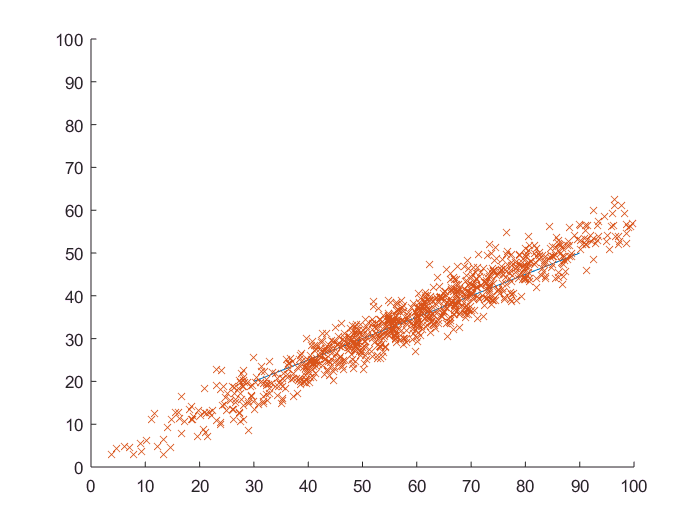

m = 1000;
for i=1:1000
x1 = randn(1,2);
x2=x1*[25 0;0 5];



x3=x2*rotation;
x(i,:) = x3+qcenter;
end
plot([qstart(1),qgoal(1)],[qstart(2),qgoal(2)])
%y=[cos(slop) -sin(slop)]
a1=qstart*rotation;
a2=qgoal*rotation;
%plot([a1(1),a2(1)],[a1(2),a2(2)])
plot(x(:,1),x(:,2),'x')